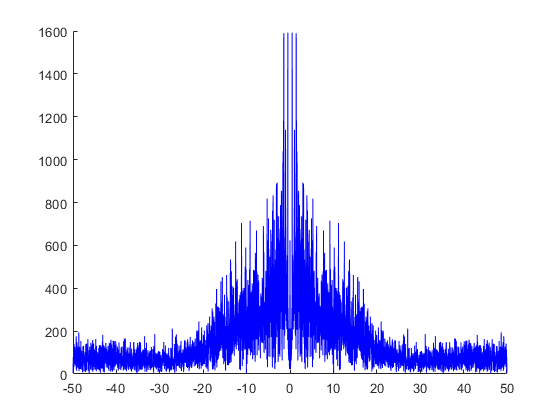

foot = csvread('form 2 foot.csv', 1,0);
pocket = csvread('form 2 pocket.csv', 1,0);
footTime = foot(:,1)';
footAbs = foot(:,5)';
footX = foot(:,2)';
footY = foot(:,3)';
footZ = foot(:,4)';


pocketTime = pocket(:,1)';
pocketAbs = pocket(:,5)';

footStartOne = 1800; %1800
footEndOne = 5800; %5800
footTimeOne = footTime(footStartOne:footEndOne);
footAbsOne = footAbs(footStartOne:footEndOne);
footXOne = footX(footStartOne:footEndOne);
footYOne = footY(footStartOne:footEndOne);
footZOne = footZ(footStartOne:footEndOne);

nFootOne = footEndOne - footStartOne + 1;
Fs = 100;
f = linspace(-Fs/2, Fs/2 - Fs/nFootOne, nFootOne) + Fs/(2*nFootOne)*mod(nFootOne, 2);
FOOTXONE = fft(footXOne);

spectrum = fftshift(abs(FOOTXONE));
freqs_hz = f;
filter_inds = -Fs*pi <= freqs_hz & freqs_hz <= -Fs*pi/2 | Fs*pi/2 <= freqs_hz & freqs_hz <= Fs*pi;
spectrum_filt = spectrum;
spectrum_filt(filter_inds) = spectrum_filt(filter_inds)/10;

clf
hold on
plot(f,fftshift(abs(FOOTXONE)),'b');
hold off


clf
hold on
plot(f, spectrum_filt, 'b')
hold off

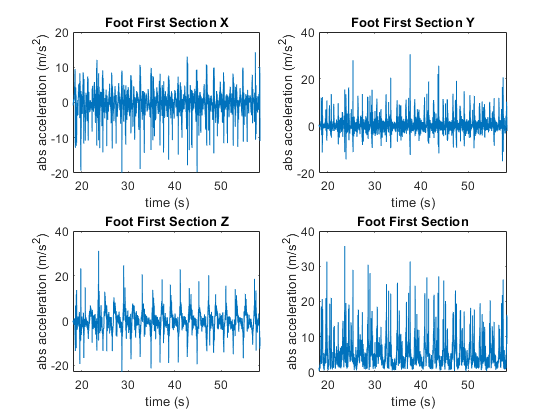


clf
subplot(2,2,1)
plot(footTimeOne, footXOne)
xlim([footTime(footStartOne),footTime(footEndOne)])
xlabel('time (s)')
ylabel('abs acceleration (m/s^2)')
title('Foot First Section X')

subplot(2,2,2)
plot(footTimeOne, footYOne)
xlim([footTime(footStartOne),footTime(footEndOne)])
xlabel('time (s)')
ylabel('abs acceleration (m/s^2)')
title('Foot First Section Y')

subplot(2,2,3)
plot(footTimeOne, footZOne)
xlim([footTime(footStartOne),footTime(footEndOne)])
xlabel('time (s)')
ylabel('abs acceleration (m/s^2)')
title('Foot First Section Z')

subplot(2,2,4)
plot(footTimeOne, footAbsOne)
xlim([footTime(footStartOne),footTime(footEndOne)])
xlabel('time (s)')
ylabel('abs acceleration (m/s^2)')
title('Foot First Section')

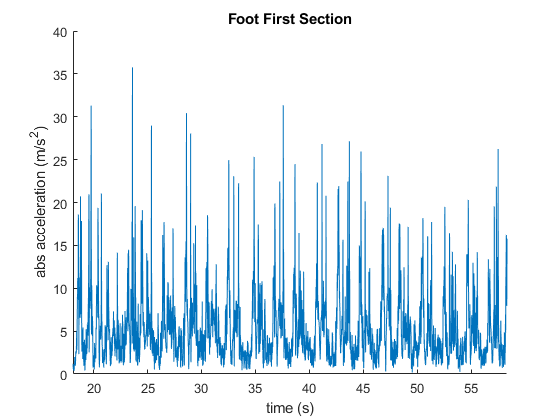



footStartTwo = 7000;
footEndTwo = 11000;
footTimeTwo = footTime(footStartTwo:footEndTwo);
footAbsTwo = footAbs(footStartTwo:footEndTwo);

pocketStartOne = 1800;
pocketEndOne = 5500;
pocketTimeOne = pocketTime(pocketStartOne:pocketEndOne);
pocketAbsOne = pocketAbs(pocketStartOne:pocketEndOne);

pocketStartTwo = 7000;
pocketEndTwo = 10500;
pocketTimeTwo = pocketTime(pocketStartTwo:pocketEndTwo);
pocketAbsTwo = pocketAbs(pocketStartTwo:pocketEndTwo);

clf;
hold on
plot(footTimeOne, footAbsOne)
xlim([footTime(footStartOne),footTime(footEndOne)])
xlabel('time (s)')
ylabel('abs acceleration (m/s^2)')
title('Foot First Section')
hold off

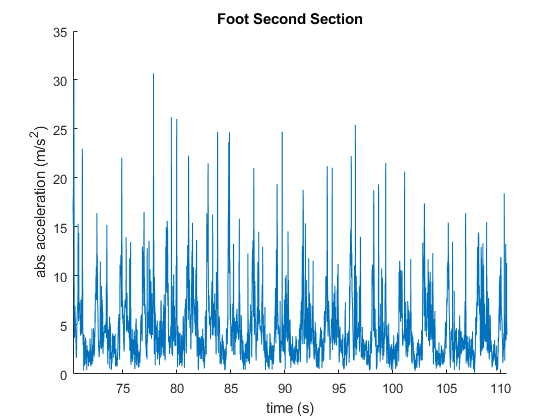


clf;
hold on
plot(footTimeTwo, footAbsTwo)
xlim([footTime(footStartTwo),footTime(footEndTwo)])
xlabel('time (s)')
ylabel('abs acceleration (m/s^2)')
title('Foot Second Section')
hold off

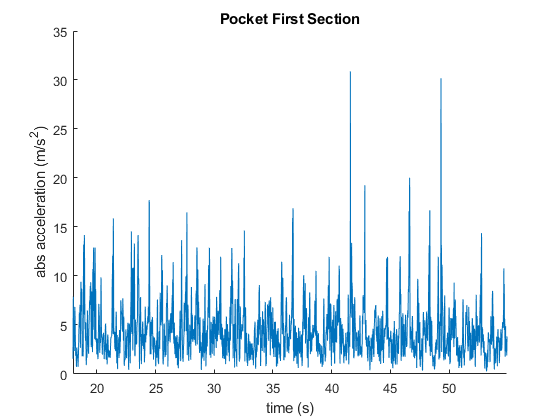


clf;
hold on
plot(pocketTimeOne, pocketAbsOne)
xlim([pocketTime(pocketStartOne),pocketTime(pocketEndOne)])
xlabel('time (s)')
ylabel('abs acceleration (m/s^2)')
title('Pocket First Section')
hold off

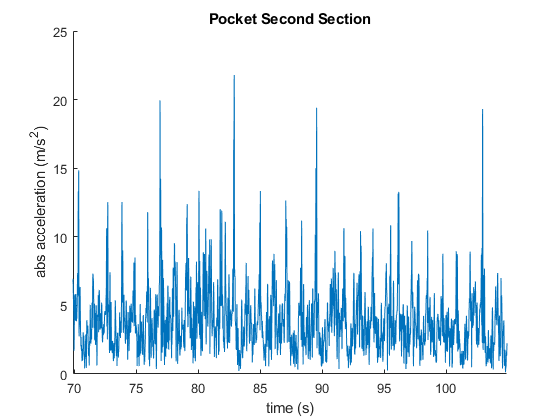


clf;
hold on
plot(pocketTimeTwo, pocketAbsTwo)
xlim([pocketTime(pocketStartTwo),pocketTime(pocketEndTwo)])
xlabel('time (s)')
ylabel('abs acceleration (m/s^2)')
title('Pocket Second Section')
hold off

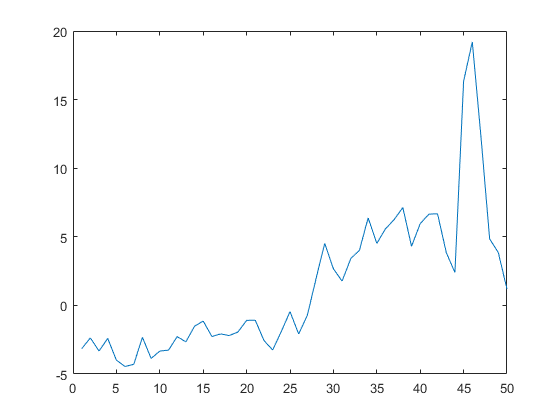


fftOne = fftshift(footAbsOne - mean(footAbsOne));
fftTwo = fftshift(footAbsTwo - mean(footAbsTwo));
fftDiff = fft(footAbsOne - footAbsTwo);
clf;
plot(real(fftOne(1:50)))

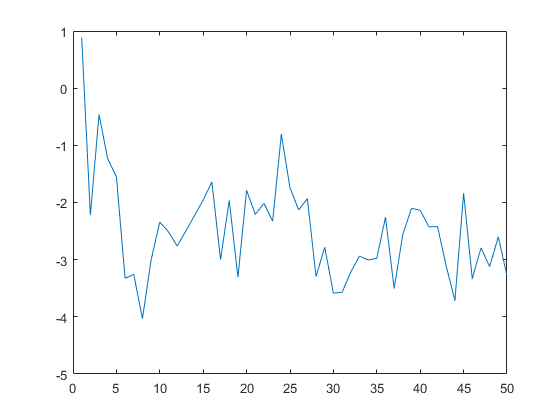

clf;
plot(real(fftTwo(1:50)))

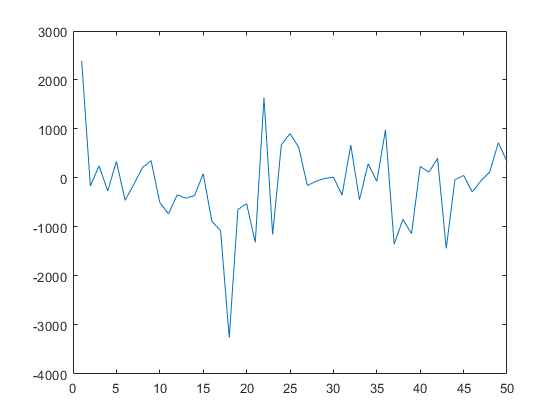

clf;
plot(real(fftDiff(1:50)))